# Water signal analysis

## Normal single and double peak fit on the data

%% Clean up from previous file
clear all;
addpath("..\..\Matlab-pipeline\SBS_pipeline\")
addpath("..\..\Matlab-pipeline\gpufit-matlab\")
% close all;
clc;

## Read and process the data

During the data aqcuisition, there was a sudden change in the laser frequency, resulting in a ~50MHz jump in measured shift of the pure water signal.

For our later analysis, we will only consider data before that jump.

index_valid_range = [4000 24000] ;

% Loading the data
folder = './220726_water240umspacer07_PT20ms_100freq_NEP200Hz_PW60ns/' ;
file_txt = 'PW60ns_x50y50z0um_xpt25ypt25z1um_PT20ms_100freq_NEP200Hz.txt' ;
file_zip = [file_txt(1:end-3) 'zip'] ; % replacing .txt by .zip
if isfile([folder file_txt])
    data = dlmread([folder file_txt],'\t',5, 1);
else 
    unzip([folder file_zip], folder) ;
    data = dlmread([folder file_txt],'\t',5, 1);
end

%%  Initialize variables - acquisition settings
% the piezo stage delay 40ms * 4 = 160 ms;
experiment_settings.samples_ignored = [5 0] ; % ignore first *5* samples, and last *10* samples
experiment_settings.shift           = [4] ;
experiment_settings.x_pixel_to_um   = 0.25 ;
experiment_settings.y_pixel_to_um   = 0.25 ;

experiment_settings.freq_num    = 100;
AOM_diff = 0.04 + 0.1;

experiment_settings.range_X     = 50; %in um
experiment_settings.range_Y     = 50; %in um
experiment_settings.n_planes    = 1 ;
experiment_settings.freq_begin  = 4.1 - AOM_diff; % in GHz
experiment_settings.freq_end    = 6.1 - AOM_diff; % in GHz

experiment_settings.pixel_X     = experiment_settings.range_X / experiment_settings.x_pixel_to_um + 1;
experiment_settings.pixel_Y     = experiment_settings.range_Y / experiment_settings.y_pixel_to_um + 1;
experiment_settings.pixel_num   = experiment_settings.pixel_X * experiment_settings.pixel_Y;

data_LIA = data(:,1);
data_LIA(experiment_settings.freq_num*2000 : experiment_settings.freq_num*2000 + 1: length(data_LIA))= [];

start = tic ;

%% Preprocessing
% Filter data
fs = experiment_settings.pixel_X*experiment_settings.pixel_Y*experiment_settings.freq_num;
% y = highpass(data_to_fit, freq_num*10, fs);
y = highpass(data_LIA, 25, 25*100);
y_shift = 1;
data_LIA = data_LIA + y_shift;
y = y + y_shift;

[data_X, data_Y] = pipeline_preprocess(y, experiment_settings.freq_begin, experiment_settings.freq_end, experiment_settings.freq_num, experiment_settings.pixel_num, experiment_settings.n_planes) ;

%% Manual correction for the first 2000 points 
% Some problem with the first data batch (a missing bit)
 data_X(:, 1:2000, 1) = data_X(:, 1:2000, 1) - (experiment_settings.freq_end - experiment_settings.freq_begin) / (experiment_settings.freq_num - 1);

%% Single peak fitting
initial_parameters = zeros(4, size(data_X, 2), 'single'); % Fits are done plane by plane
initial_parameters(1, :) = 1 ; % Amplitude
initial_parameters(2, :) = (experiment_settings.freq_begin + experiment_settings.freq_end) /2-0.2;  % x_0
initial_parameters(3, :) = (experiment_settings.freq_end - experiment_settings.freq_begin) / 7.5; % gamma
initial_parameters(4, :) = 0.7; % offset

constraints = zeros([2*4, size(data_X, 2)], 'single'); % Fits are done plane by plane
constraints(1, :) = 0.35; % Min amplitude
constraints(2, :) = 2; % Max amplitude
constraints(3, :) = experiment_settings.freq_begin + 0.2; % Min x_0
constraints(4, :) = experiment_settings.freq_end - 0.1; % Max x_0
constraints(5, :) = 0.2; % Min gamma
constraints(6, :) = 0.7; % Max gamma
constraints(7, :) = 0.4; % Min offset
constraints(8, :) = 1; % Max offset

[volume, single_fit] = pipeline_single_peak(data_X, data_Y, ...
    experiment_settings, initial_parameters, constraints );




%% Double peak fitting
[volume_single_peak, volume_double_peak, single_peak, double_peak] =...
    pipeline_double_peak(data_X, data_Y, experiment_settings, ...
    single_fit, constraints);



%% Computing statistics
[AIC] = pipeline_analyze_fit(data_X, data_Y, volume_single_peak, volume_double_peak);

%These value com from the analysis further down - just for visualization
spectral_resolution = (experiment_settings.freq_end - experiment_settings.freq_begin) / experiment_settings.freq_num ;
n = 5 ;
delta = 0.5 ;
AIC.double_peaks = double_peak_criteria(volume_double_peak, spectral_resolution, n, delta) ;

## Displaying

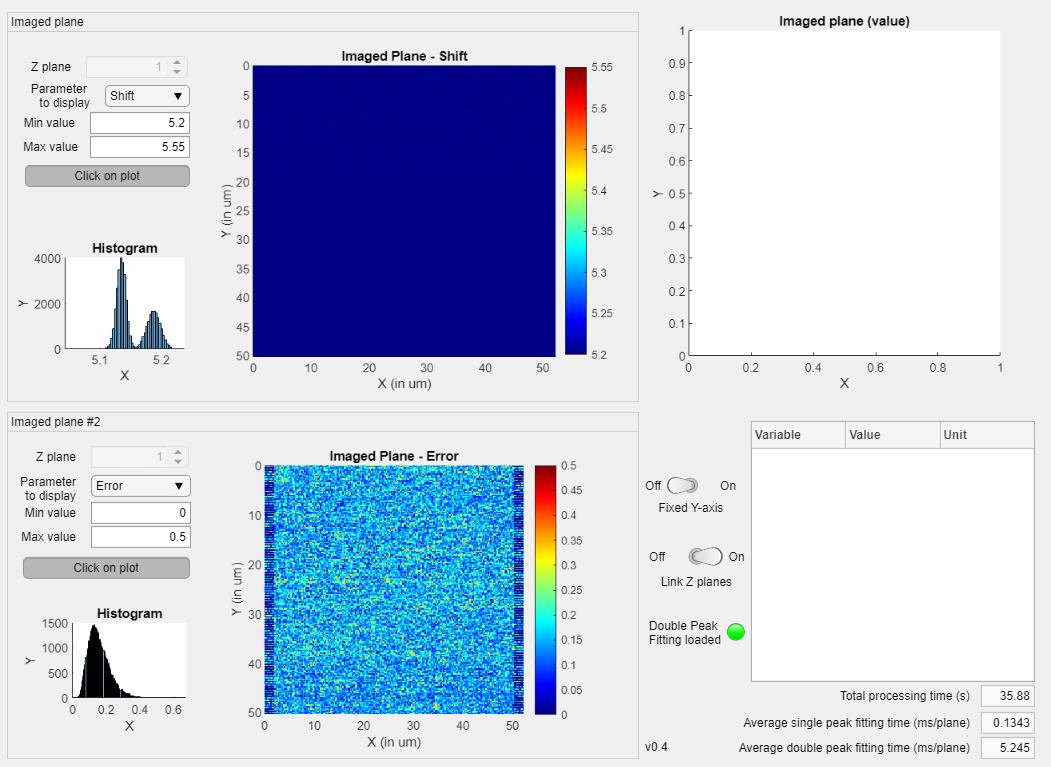

experiment_settings.total_processing_time = toc(start) ;
volume_display(experiment_settings, volume_single_peak, volume_double_peak, AIC);

## Testing the double peak criteria with different values

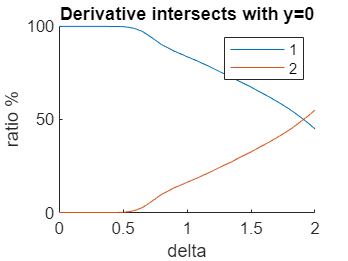

spectral_resolution = (experiment_settings.freq_end - experiment_settings.freq_begin) / experiment_settings.freq_num ;
n = 5 ;

test = zeros([1, index_valid_range(2)]);

ratio_1 = [] ;
ratio_2 = [] ;
delta_x = [] ;
for delta = 0:0.05:2
    for i = index_valid_range(1):index_valid_range(2) 
        % We're doing this over the 1D array, so we can't use the function
            
            x = double_peak.parameters(2,i)-n*spectral_resolution:spectral_resolution:double_peak.parameters(5,i)+n*spectral_resolution ;
           
            deriv = deriv_L1_L2(x, ...
                double_peak.parameters(1,i), double_peak.parameters(3,i), double_peak.parameters(2,i),...
                double_peak.parameters(4,i), double_peak.parameters(5,i), double_peak.parameters(6,i)) ;
            
            list = [size(find(diff(sign(deriv))),2)];
            for t = -delta:0.05:delta
                list = [list size(find(diff(sign(deriv + t))),2)];
            end
            test(i) = max(list);

    end
    ratio_1(end+1) = sum(test(4000:end) == 1) / (size(test(4000:end), 2)) ;
    ratio_2(end+1) = sum(test(4000:end) == 2) / (size(test(4000:end), 2)) ;
    delta_x(end+1) = delta ;
end

clf
hold on
plot(delta_x, ratio_1 * 100, 'DisplayName', '1') ;
plot(delta_x, ratio_2 * 100, 'DisplayName', '2') ;
legend
xlabel("delta") ;
ylabel("ratio %") ;
title("Derivative intersects with y=0")